count = 5

count = 5

T_i = 300 %Boundary values

T_i = 300

T_f = 400

T_f = 400

tridiag = 	1.0e+04 *

   -2.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000   -2.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

tridiag = 	1.0e+04 *

   -2.0040    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0020   -2.0040    1.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

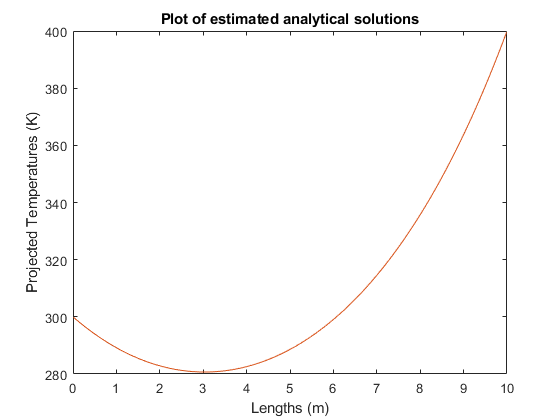


for count = 1000:1001
    %Technically +1 subinterval
    delta = 10/count;
    xbase = (delta:delta:10-delta);
    c = 1/delta.^2;
    a = c;
    b = -(2/(delta.^2)+0.05);
    
    expectedOut = -10*(ones(1, count-1));
    expectedOut(1) = -10 - a*T_i;
    expectedOut(count-1) = -10 - c*T_f;
    oneTemp = b.*ones(1, count-1);
    tridiag = diag(oneTemp);
    for i = 2:count-2
        tridiag(i, i-1) = a;
        tridiag(i, i+1) = c;
    end
    tridiag(1, 2) = c;
    tridiag(count-1, count-2) = a
    X = mldivide(tridiag, expectedOut.');
    title('Plot of estimated analytical solutions');
    xlabel('Lengths (m)');
    ylabel('Projected Temperatures (K)');
    timeStep = num2str(count);
    plot(xbase, X, 'DisplayName', strcat('Approx for ', timeStep));
    hold on;
     
end